**COT 5930 Image processing, spring 2021  -- Christian Garbin**

# Assignment 5: Image classification

Code in this live script was created based on the starter code. All unattributed text and code should be assumed to be from the starter code. All  mistakes an dpoorly written pieces of code are mine.

## Model

% Use a pretrained network
model = alexnet;

## Dataset

Create the dataset, backed by images on disk, adpated through an imageDatastore.

categories = {'cat', 'dog'};
[trainingSet, validationSet] = getDataset( ...
    './data/kaggle', categories, 0.7, true);

Dataset distribution before rebalancing
    Label    Count
    _____    _____

     cat      200 
     dog      200 

Dataset distribution after rebalancing
    Label    Count
    _____    _____

     cat      200 
     dog      200 

Training set distribution
    Label    Count
    _____    _____

     cat      140 
     dog      140 

Validation set distribution
    Label    Count
    _____    _____

     cat      60  
     dog      60  



## Transfer learning

Reuse (freeze) all layers, but the last three. This is where the classificaiton happens, so we need to adapt it to our case, where we have two classes (cats and dogs).

layersTransfer = model.Layers(1:end-3);
numClasses = 2; % cat and dog

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

Configuration

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',validationSet, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

Retrain the network

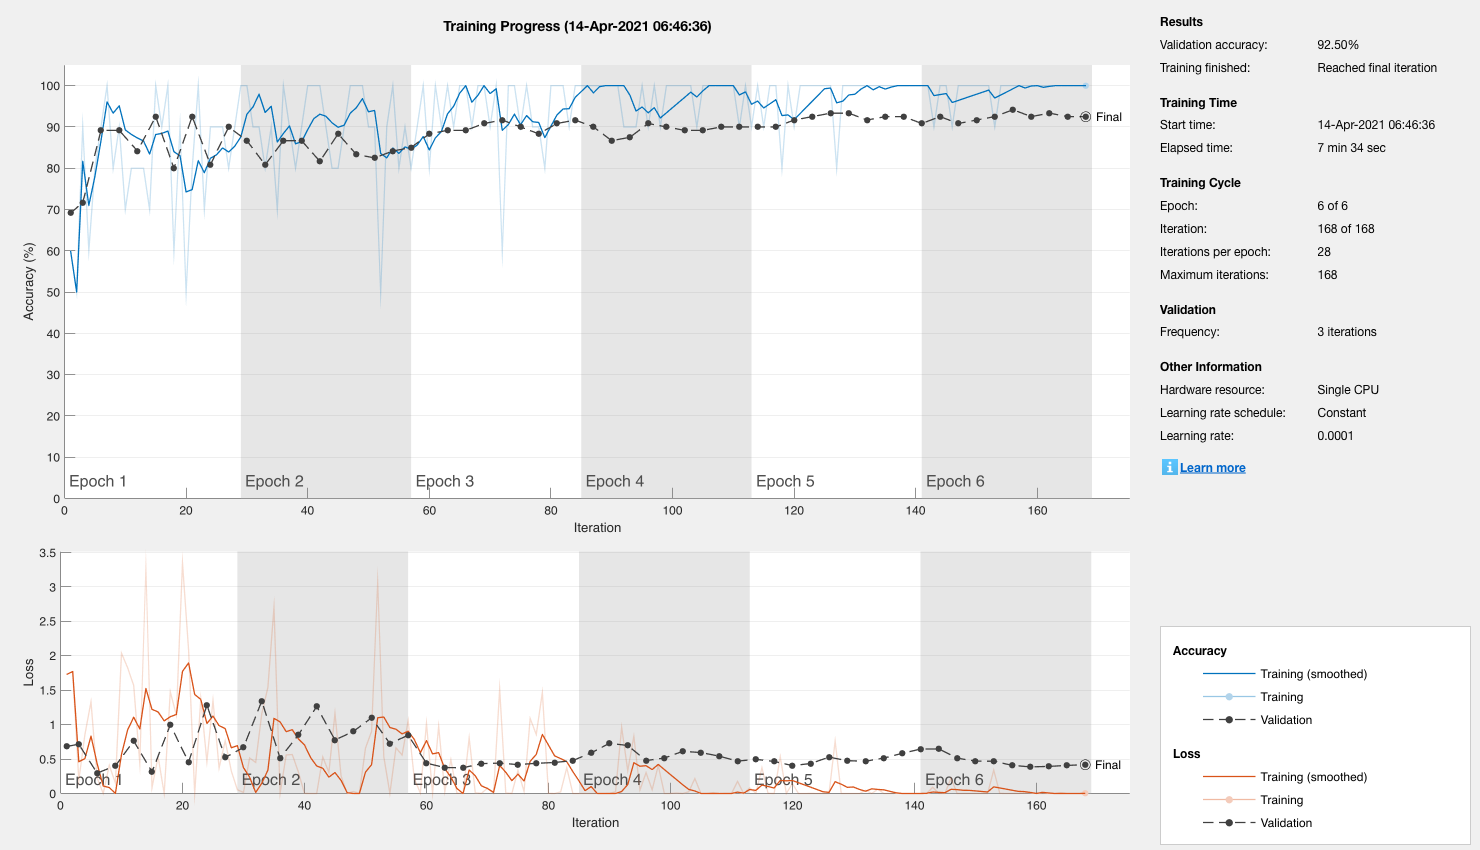

modelTransfer = trainNetwork(trainingSet,layers,options);

Predict scores on the validation set and calculate accuracy.

[YPred,scores] = classify(modelTransfer,validationSet);

YValidation = validationSet.Labels;
accuracy = mean(YPred == YValidation);
fprintf("The validation accuracy is: %.2f %%\n", accuracy * 100);

The validation accuracy is: 92.50 %


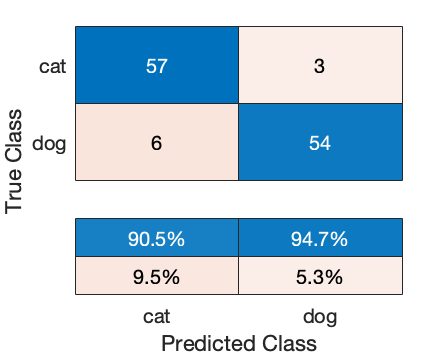

confusionchart(YValidation,YPred, "ColumnSummary","column-normalized")

### Predict specific images

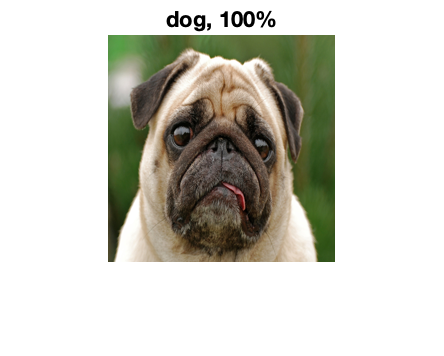

predictAndShow('./dog.jpg',modelTransfer,categories)

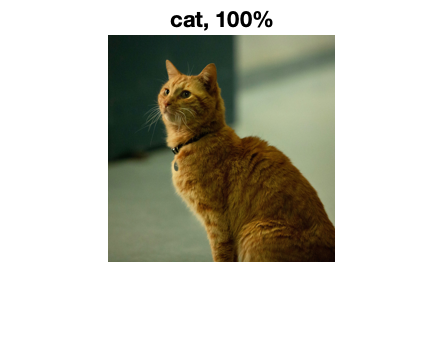

predictAndShow('./cat.jpg',modelTransfer,categories)

## Data augmentation

imageAugmentation object.

% In our case, we shall use an augmented image datastore to randomly flip
% the training images along the vertical axis and randomly translate them
% up to 30 pixels and scale them up to 10% horizontally and vertically.
pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

Augmented training and validation sets.

inputSize = model.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainingSet, ...
    'DataAugmentation',imageAugmenter);

disp(augimdsTrain.NumObservations) % You should see 28

   280




augimdsValidation = augmentedImageDatastore(inputSize(1:2),validationSet);

disp(augimdsValidation.NumObservations) % You should see 12

   120



## Retrain with augmented data

miniBatchSize = 10;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',3e-4, ...
    'ValidationData',augimdsValidation, ...
    'Verbose',false, ...
    'Plots','training-progress');

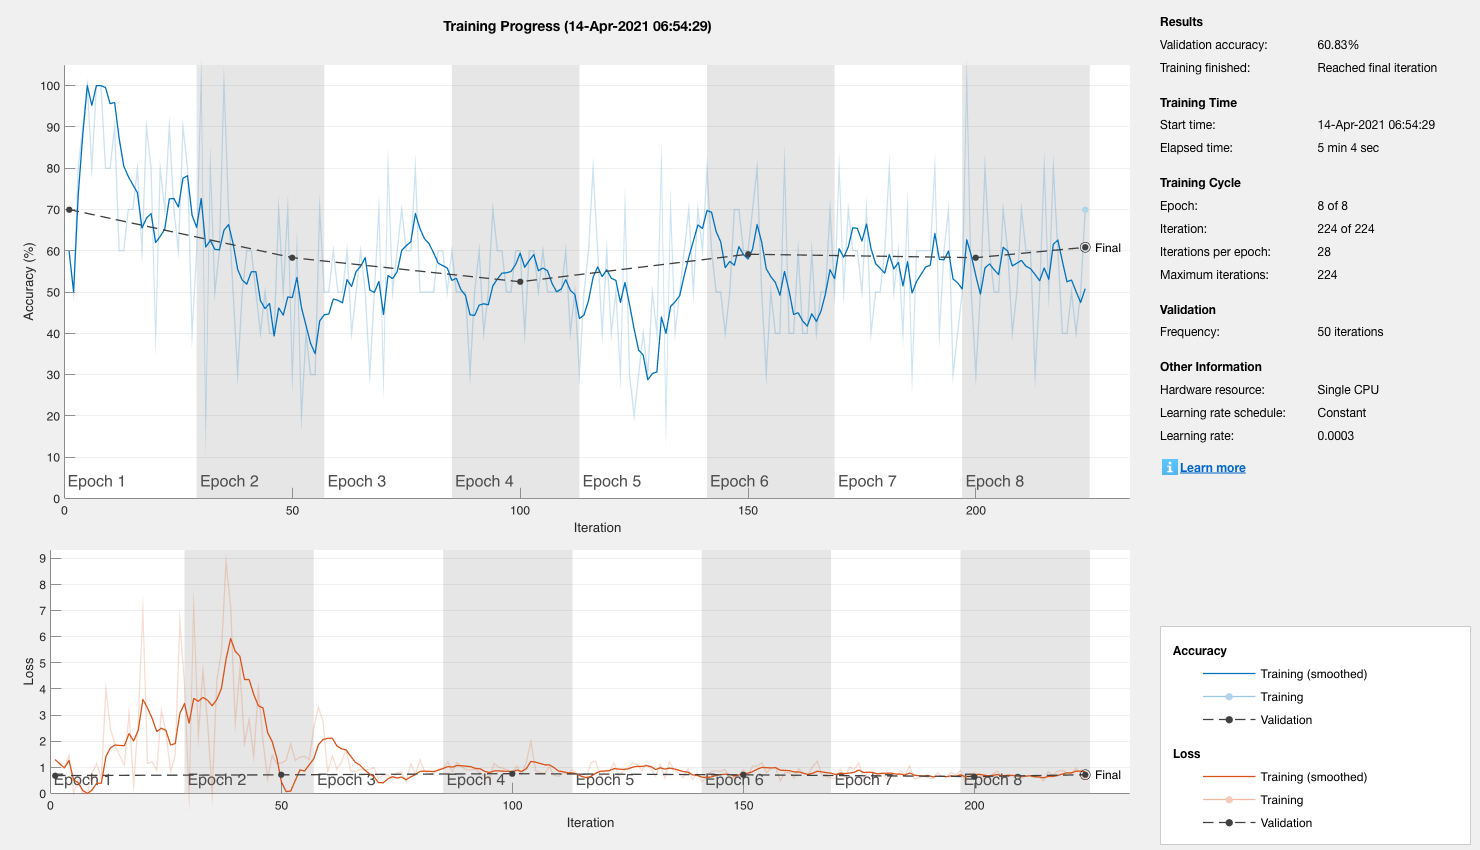

modelAug = trainNetwork(augimdsTrain,layers,options);

Predict scores on the validation set and calculate accuracy.

[YPredAug,probsAug] = classify(modelAug,augimdsValidation);

YValidationAug = validationSet.Labels;
accuracyAug = mean(YPredAug == YValidationAug);
fprintf("The validation accuracy is: %.2f %%\n", accuracyAug * 100);

The validation accuracy is: 60.83 %


## Auxiliary functions

Create a dataset backed by an image store. The function assumes there are only two categories and that the directory structure is correctly split into these categories (the name of the directories mus match the name of the categories for the `imageDatastore` to work correctly).

function [trainingSet, validationSet] = getDataset( ...
    dataFolder, categories, trainPercentage, verbose)

    function showStats(text, imds)
        if verbose
            tempTbl = countEachLabel(imds);
            disp(text)
            disp(tempTbl)
        end
    end

    imds = imageDatastore(fullfile(dataFolder, categories), 'LabelSource', 'foldernames');
    showStats('Dataset distribution before rebalancing', imds)
   
    % Ensure the categories are balanced by using the smallest overlap set (may not be
    % needed for some datasets, but protects in case we use an unbalanced dataset
    % without realizing it).
    tbl = countEachLabel(imds);
    minSetCount = min(tbl{:,2});
    % Trim the set.
    imds = splitEachLabel(imds, minSetCount, 'randomize');
    % Each set must now have exactly the same number of images.
    showStats('Dataset distribution after rebalancing', imds)
    
    % AlexNet can only process RGB images that are 227-by-227
    % To avoid re-saving all the images to this format, setup the |imds| read function,
    % |imds.ReadFcn|, to pre-process images on-the-fly. The |imds.ReadFcn| is called
    % every time an image is read from the |ImageDatastore|
    imds.ReadFcn = @(filename)readAndPreprocessImage(filename);
    
    [trainingSet, validationSet] = splitEachLabel(imds, trainPercentage, 'randomized');
    showStats('Training set distribution', trainingSet)
    showStats('Validation set distribution', validationSet)
end

Show an image and its prediction.

function predictAndShow(file, model, categories)
    image = file;
    image = readAndPreprocessImage(image);
    pred = predict(model, image);
    [confidence,idx] = max(pred);
    label = categories{idx};
    % Display test image and assigned label
    figure
    imshow(image)
    title(string(label) + ", " + num2str(100*confidence) + "%");
end